# **[Self] Chapter 14 Mini Quiz (Mini Quiz Lec09) [ALL CORRECT]**

format short
xtest1 = 1.1

xtest1 = 1.1000

xtest2 = 1.5

xtest2 = 1.5000

xtest3 = 45

xtest3 = 45

## **Exponential**

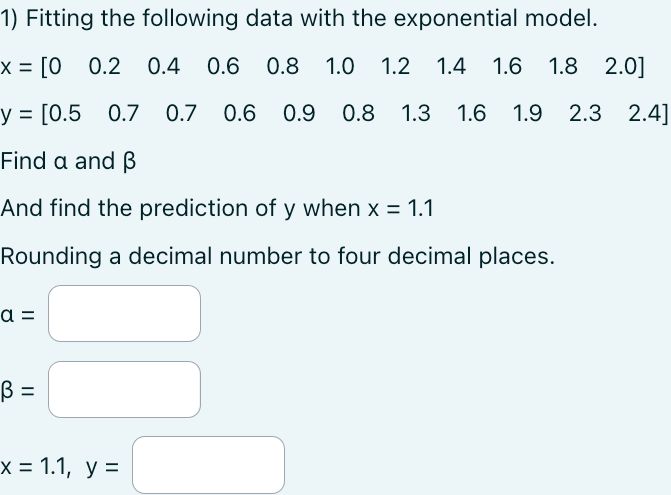

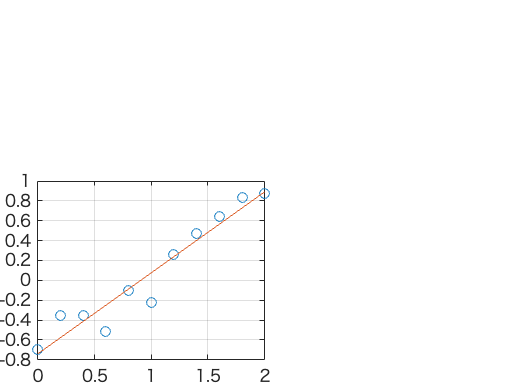

ae =     0.8148   -0.7388


x = [0 0.2 0.4 0.6 0.8 1.0 1.2 1.4 1.6 1.8 2.0];
y = [0.5 0.7 0.7 0.6 0.9 0.8 1.3 1.6 1.9 2.3 2.4];
x_exp = x;
y_exp = log(y);
[ae, ~] = linregr(x_exp, y_exp)

alphae = exp(ae(2))

alphae = 0.4777

betae = ae(1)

betae = 0.8148

yprede = alphae .* exp(betae .* xtest1)

yprede = 1.1706

## **Power**

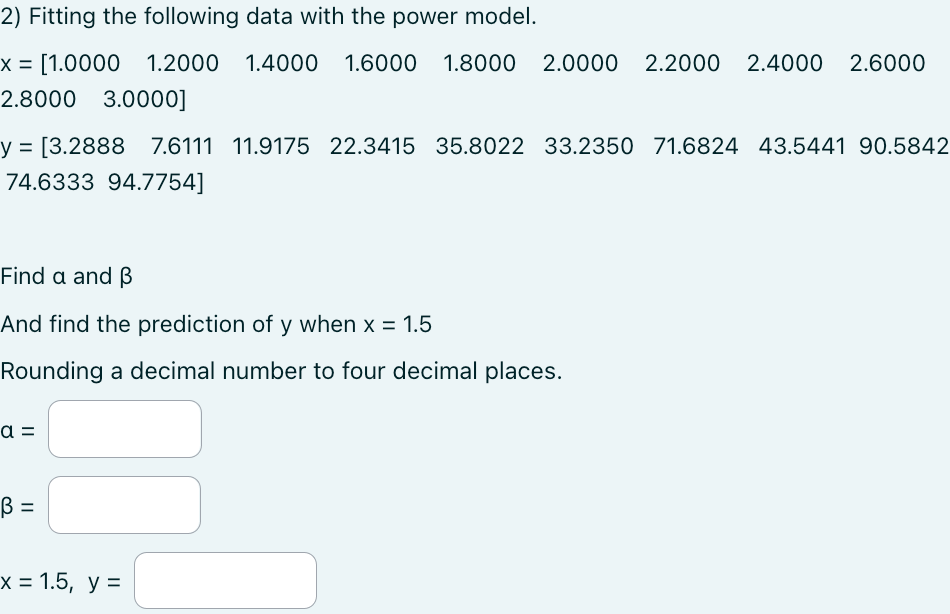

x = [1.0000 1.2000 1.4000 1.6000 1.8000 2.0000 2.2000 2.4000 2.6000 2.8000 3.0000];
y = [3.2888 7.6111 11.9175 22.3415 35.8022 33.2350 71.6824 43.5441  90.5842 74.6333  94.7754];
x_pow = log10(x)

x_pow =          0    0.0792    0.1461    0.2041    0.2553    0.3010    0.3424    0.3802    0.4150    0.4472    0.4771


y_pow = log10(y)

y_pow =     0.5170    0.8814    1.0762    1.3491    1.5539    1.5216    1.8554    1.6389    1.9571    1.8729    1.9767


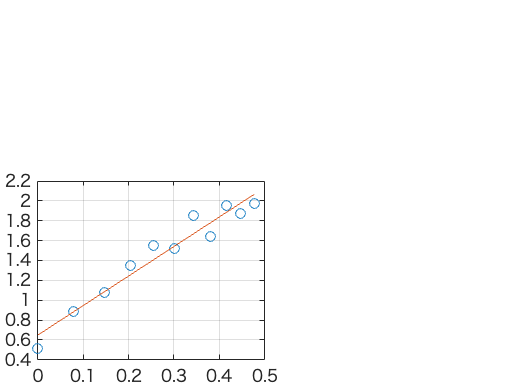

ap =     2.9712    0.6496


[ap, ~] = linregr(x_pow, y_pow)

alphap = 10^ap(2)

alphap = 4.4625

betap = ap(1)

betap = 2.9712

ypredp = alphap .* (xtest2 .^ betap)

ypredp = 14.8858

## **Saturation**

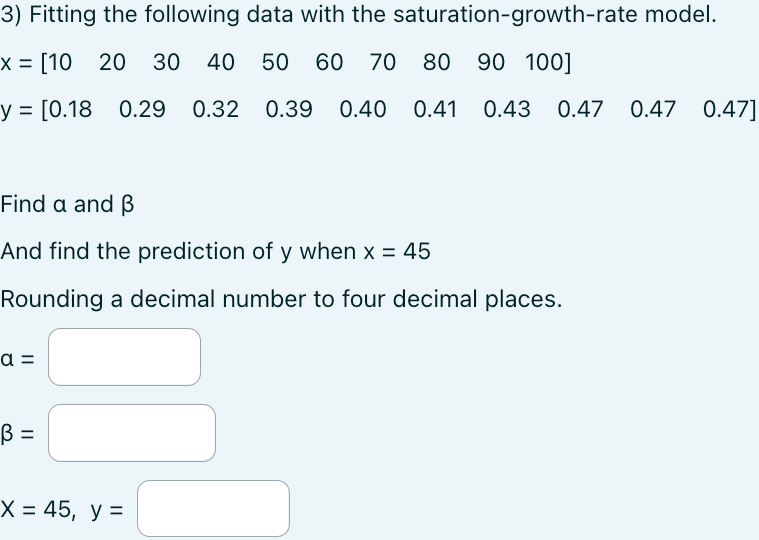

x = [10 20 30 40 50 60 70 80 90 100];
y = [0.18 0.29 0.32 0.39 0.40 0.41 0.43 0.47 0.47 0.47];
x_sat = 1 ./ x

x_sat =     0.1000    0.0500    0.0333    0.0250    0.0200    0.0167    0.0143    0.0125    0.0111    0.0100


y_sat = 1 ./ y

y_sat =     5.5556    3.4483    3.1250    2.5641    2.5000    2.4390    2.3256    2.1277    2.1277    2.1277


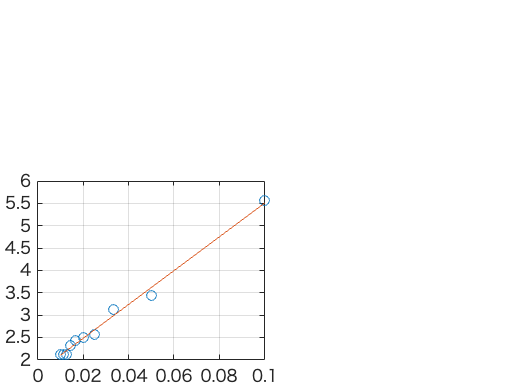

as =    37.8012    1.7269


[as, ~] = linregr(x_sat, y_sat)

alphas = 1 / as(2)

alphas = 0.5791

betas = as(1) * alphas

betas = 21.8901

ypreds = alphas .* (xtest3 ./ (betas + xtest3))

ypreds = 0.3896